img_name="../matting_cvpr06/kid1.bmp"

img_name = "../matting_cvpr06/kid1.bmp"

%'../../dataset/shadow/_MG_6375.jpg'
%"../matting_cvpr06/kid1.bmp"
scribs_img_name="../matting_cvpr06/kid1_m.bmp"

scribs_img_name = "../matting_cvpr06/kid1_m.bmp"

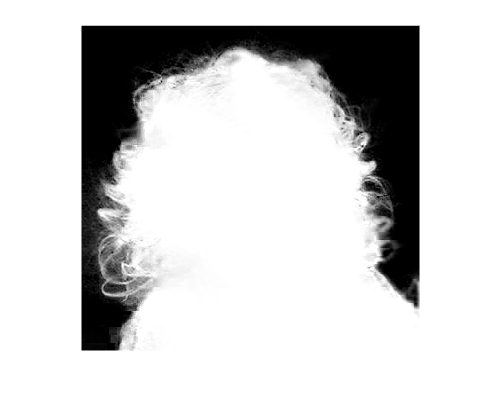

%"../matting_cvpr06/kid1_test.bmp"
%'../../dataset/shadow_scribes/_MG_6375.jpg'
%"../matting_cvpr06/kid1_test.bmp"


% hyper params
levels_num=1;
active_levels_num=1;
sig=0.1^5;

function y = normalize2uint8(x)
    x = real(x);
    min_value = min(reshape(x,1,[]));
    max_value = max(reshape(x,1,[]));
    scale = 255./(max_value - min_value);
    bias = -1. * min_value * scale;
    y = scale * x + bias;
    y = uint8(y);
end

if (~exist('thr_alpha','var'))
  thr_alpha=[];
end
if (~exist('epsilon','var'))
  epsilon=[];
end
if (~exist('win_size','var'))
  win_size=[];
end

if (~exist('levels_num','var'))
  levels_num=1;
end  
if (~exist('active_levels_num','var'))
  active_levels_num=1;
end  

I=double(normalize2uint8(imread(img_name)))/255;
mI=double(normalize2uint8(imread(scribs_img_name)))/255;
consts_map=sum(abs(I-mI),3)>0.001;
if (size(I,3)==3)
  consts_vals=rgb2gray(mI).*consts_map;
end
if (size(I,3)==1)
  consts_vals=mI.*consts_map;
end



alpha=solveAlphaC2F(I,consts_map,consts_vals,levels_num, ...
                    active_levels_num,thr_alpha,epsilon,win_size);

figure, imshow(alpha);

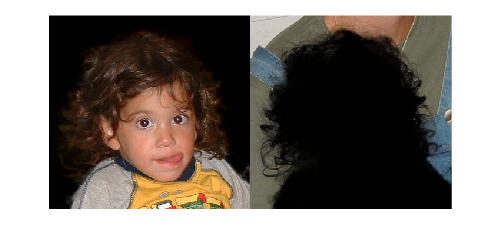

drawnow;
[F,B]=solveFB(I,alpha);

figure, imshow([F.*repmat(alpha,[1,1,3]),B.*repmat(1-alpha,[1,1,3])])